# Validation of Physics-Based Image Systems Simulation with 3D Scenes

## Figure 3

## 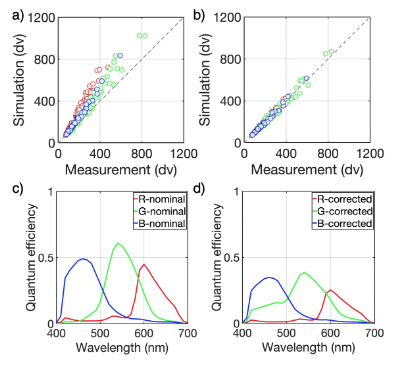

Fig. 3. Sensor spectral quantum efficiency calibration. (a) Scatter plot comparing measured and simulated RGB values of the MCC based on nominal color filter quantum efficiency. (b) Scatter plot comparing measured and simulated RGB values after correction for cross-talk and channel gain. (c) Nominal color filter quantum efficiency and (d) quantum efficiency after correction

### Read in the Pixel4a data

% These are the pixel 4a vignetting measurements
load('p4aLensVignet_dc_p55_pos1.mat', 'pixel4aLensVignetSlope');
vignetting = pixel4aLensVignetSlope;

% Directory where the Pixel 4A quantum efficiency is stored
qeDir = fullfile(cboxRootPath, 'data', 'measurement', 'QEcalibration');

% Check the accuracy in the middle with everything on 

% Read in the mean values of the measurements
illuminantType = {'A', 'day', 'cwf'};
pos = {'midcenter'};
cornerPointsMeas = {[1858 1408 2229 1656],...
                    [1858 1408 2229 1656],...
                    [1858 1408 2229 1656]};

% The number of illuminant types (3) times the number of positions to
% sample (1)
nFrames = numel(illuminantType) * numel(pos);
imgNames = cell(1, nFrames);
illuminants = cell(1, nFrames);

cnt = 1;
for ii=1:numel(illuminantType)
    thisIllu = illuminantType{ii};
    
    curIlluDir = fullfile(qeDir, thisIllu);
    
    for jj=1:numel(pos)
        thisDngFile = dir(fullfile(curIlluDir, pos{jj}, '*.dng'));
        imgNames{cnt} = fullfile(curIlluDir, pos{jj},thisDngFile(1).name);
        illuminants{cnt} = thisIllu;
        cnt = cnt + 1;
    end
end


#### Get the rgb mean value in mid center of each of the 24 MCC patches from the DNG file (raw data file)

We use these data as the ground-truth to compare with the simulations.

rgbMeanMeasMidCenter = zeros(nFrames * 24, 3);

for ii=1:numel(imgNames)
    thisCropMeas = cornerPointsMeas{ii};
    thisIllu = illuminants{ii};
    
    % Get the mean rgb for this sensor
    [thisSensorMeas, thisInfo, thisRGBMeanMeas, ~] = ...
        cbMccChipsDV(imgNames{ii},...
        'corner point', thisCropMeas,...
        'vignetting', vignetting);
    
    % 24 (patches) 3 (illuminants) x 3 (rgb)
    rgbMeanMeasMidCenter((ii-1) * 24+1:ii*24,:) = thisRGBMeanMeas;
end

Black border
Black border
Black border


### Calculate simulated signal

Compare the scene and oi for each of the illuminants using the known MCC reflectances.

wave = 390:10:710;   % Wavelength samples for the simulation
lightNameA   = 'illA-20201023.mat';   % Tungsten (A)
lightNameCWF = 'illCWF-20201023.mat'; % CWF
lightNameDay = 'illDay-20201023.mat'; % Daylight
patchSize = 32;

% What do these do?
[sceneA, oiA] = cbMccSceneOISim('illuminant', lightNameA, 'wave', wave,...
                                'patch size', patchSize);
[sceneCWF, oiCWF] = cbMccSceneOISim('illuminant', lightNameCWF, 'wave', wave,...
                                'patch size', patchSize);       
[sceneDay, oiDay] = cbMccSceneOISim('illuminant', lightNameDay, 'wave', wave,...
                                'patch size', patchSize);


### We read Pixel 4a dng-data into a sensor model 

First we use the sensor model with the corrected color filter estimates

The first sensor model has the corrected color filters.  See the script (XXXX) for how we calculated the corrected QE values.

cornerPointsSim = [165 160 1089 770];
sensorSimCor = cbDNGRead(imgNames{3}, 'demosaic', false);
blkLvl = sensorGet(sensorSimCor, 'black level');

Compute the sensor response without color filter correction

sensorSimNoCor = cbDNGRead(imgNames{3}, 'demosaic', false, 'transcolorfilter', false);
[~, rgbMeanANoCor, ~]   = cbMccSensorSim(oiA, sensorSimNoCor, cornerPointsSim);

Black border


[~, rgbMeanDayNoCor, ~] = cbMccSensorSim(oiDay, sensorSimNoCor, cornerPointsSim);

Black border


[~, rgbMeanCWFNoCor, ~] = cbMccSensorSim(oiCWF, sensorSimNoCor, cornerPointsSim);

Black border



rgbMeanSimNoCorMidCenter = [rgbMeanANoCor;rgbMeanDayNoCor;rgbMeanCWFNoCor];

Make sure the simulated sensor data w/o correction DOES NOT match the measurement

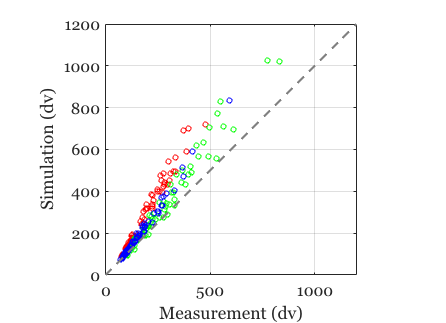

ieNewGraphWin; 
hold all;
plot(rgbMeanMeasMidCenter(:,1) + blkLvl, rgbMeanSimNoCorMidCenter(:,1)+ blkLvl,'ro','MarkerSize', 5); identityLine;
plot(rgbMeanMeasMidCenter(:,2)+ blkLvl, rgbMeanSimNoCorMidCenter(:,2)+ blkLvl,'go','MarkerSize', 5); identityLine;
plot(rgbMeanMeasMidCenter(:,3)+ blkLvl, rgbMeanSimNoCorMidCenter(:,3)+ blkLvl,'bo','MarkerSize', 5); identityLine;
axis square; box on;
identityLine;
xlabel('Measurement (dv)'); ylabel('Simulation (dv)');
xlim([0 1200]); ylim([0 1200])

% Get the black level

[~, rgbMeanACor, ~]   = cbMccSensorSim(oiA, sensorSimCor, cornerPointsSim);

Black border


[~, rgbMeanDayCor, ~] = cbMccSensorSim(oiDay, sensorSimCor, cornerPointsSim);

Black border


[~, rgbMeanCWFCor, ~] = cbMccSensorSim(oiCWF, sensorSimCor, cornerPointsSim);

Black border



rgbMeanSimCorMidCenter = [rgbMeanACor;rgbMeanDayCor;rgbMeanCWFCor];


Make sure the simulated sensor data match the measurement

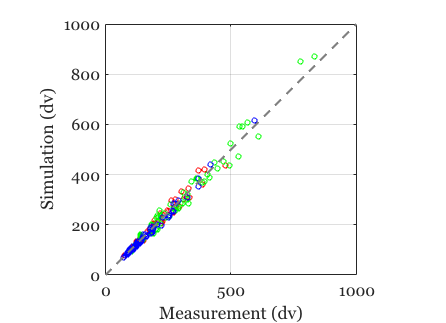

ieNewGraphWin; 
hold all;
plot(rgbMeanMeasMidCenter(:,1) + blkLvl, rgbMeanSimCorMidCenter(:,1)+ blkLvl,'ro', 'MarkerSize', 5); 
plot(rgbMeanMeasMidCenter(:,2)+ blkLvl, rgbMeanSimCorMidCenter(:,2)+ blkLvl,'go', 'MarkerSize', 5);
plot(rgbMeanMeasMidCenter(:,3)+ blkLvl, rgbMeanSimCorMidCenter(:,3)+ blkLvl,'bo', 'MarkerSize', 5);
axis square; box on;
identityLine;
xlabel('Measurement (dv)'); ylabel('Simulation (dv)');

### Plot and compare the sensor quantum efficiencies

Uncorrected sensor QE

wave       = sensorGet(sensorSimCor,'wave');
filterCorr = sensorGet(sensorSimCor, 'color filters');
filterOriRGB = sensorGet(sensorSimNoCor, 'color filters');
filterOriIr  = sensorGet(sensorSimNoCor, 'irfilter');
filterOri    = filterOriRGB .* filterOriIr;

Original filters

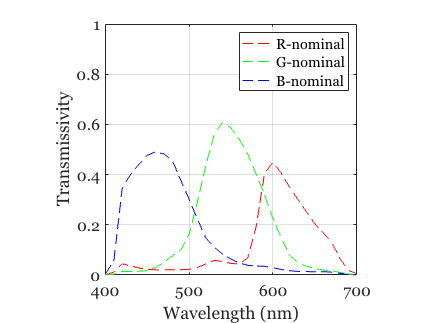

ieNewGraphWin;
hold all;
plot(wave, filterOri(:,1), 'r--');
plot(wave, filterOri(:,2), 'g--');
plot(wave, filterOri(:,3), 'b--');
box on; xlim([400 700]); ylim([0 1]); grid on;
xlabel('Wavelength (nm)'); ylabel('Transmissivity');
legend('R-nominal', 'G-nominal', 'B-nominal');
axis square;

Corrected sensor QE

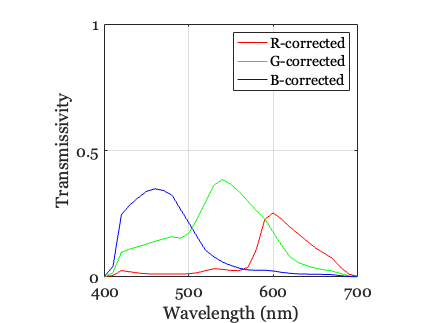


ieNewGraphWin;
hold all;
box on; xlim([400 700]); ylim([0 1]); grid on;yticks(0:0.5:1);
plot(wave, filterCorr(:,1), 'r');
plot(wave, filterCorr(:,2), 'g');
plot(wave, filterCorr(:,3), 'b');
xlabel('Wavelength (nm)'); ylabel('Transmissivity');
legend('R-corrected', 'G-corrected', 'B-corrected');
axis square;

### QE conversion matrix calculation

illuminantType = {'A', 'day', 'cwf'};
pos = {'midcenter'};
cornerPointsMeas = {[1858 1408 2229 1656],...
                    [1858 1408 2229 1656],...
                    [1858 1408 2229 1656]};
%}

cornerPointsSim = [147 115 1086 737];
nFrames = numel(illuminantType) * numel(pos);
imgNames = cell(1, nFrames);
illuminants = cell(1, nFrames);
% Counter
cnt = 1;
for ii=1:numel(illuminantType)
    thisIllu = illuminantType{ii};
    
    curIlluDir = fullfile(qeDir, thisIllu);
    
    for jj=1:numel(pos)
        thisDngFile = dir(fullfile(curIlluDir, pos{jj}, '*.dng'));
        imgNames{cnt} = fullfile(curIlluDir, pos{jj},thisDngFile(1).name);
        illuminants{cnt} = thisIllu;
        cnt = cnt + 1;
    end
end

#### Call the function that estimates the corrected QE.

[cQE, mMC, rgbMeanSimMC, rgbMeanMeasMC] = cbQEAnalysis(imgNames, illuminants,...
                        cornerPointsMeas, cornerPointsSim,...
                        vignetting, 'method', 'nonnegative','fluoremove', true);

Black border
Black border
Black border
Black border
Black border
Black border

Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Min

disp('color filter conversion matrix:')

color filter conversion matrix:


disp(mMC)

    0.5636    0.0807    0.0069
    0.0000    0.5917    0.0000
    0.0000    0.2470    0.7098

